# Testbed for Trust-based Mobile Crowd Sensing System

## Testbed:

Initially, the testbed contains 1000 users that consist of 250 high quality users, 500 low quality users and 250 malicious users.

Let shuffle  all types of the users in a 1000-element array (shuffledArray)

The number of high quality users, low quality users and malicious users will be changed in order for the comparison between trust-based MCS system and a QoI-based MCS system.

## Scenarios:

- A mobile device user could be either a sensing service provider for one task and a sensing service requester for another task.

- We run 1000 sensing tasks, each task requires a number of sensing service providers from 2 to 500. Each task is associated with a specific user as the sensing service requester.

- Will calculate the average of the QoD after 1000 tasks for comparison between trust-based MCS and QoD-based MCS


hqusers_num = 50;
lqusers_num = 50;
mausers_num = 25;
users_num = 200;

tasks_num = 1000;

provider_min = 2;
provider_max = round(users_num/2);

## Starting to build...

## Setup the users

- The high quality users behave according to the model proposed in user models files so that their QoDs follow a beta distribution: 

- Alpha is randomly set in the range [10-15]

- Beta is randomly set in the range [3.0-5.0]

x = linspace(0, 1, 1000);
hold on;
hqusers_mat = zeros(hqusers_num, tasks_num);
for i=1:hqusers_num
    ah = rand()*5 + 10; % random number in the range [10-15]
    bh = rand()*2 + 3; % random number in the range [3.0-5.0]
    hqusers_pd = makedist('Beta', 'a', ah, 'b', bh);
    hqusers_mat(i,:) = random(hqusers_pd, 1, tasks_num);
    plot(x, pdf(hqusers_pd, x), 'Color', [i/hqusers_num, 0, 1]);
end

     2. The low quality users behave according to the model proposed in user models files so that their QoDs follow a beta distribution: 

- Alpha is randomly set in the range [9-12]

- Beta is randomly set in the range [7-9]

lqusers_mat = zeros(lqusers_num, tasks_num);
for i=1:lqusers_num
    al = rand()*3 + 9; % random number in the range [9-12]
    bl = rand()*2 + 7; % random number in the range [7-9]
    lqusers_pd = makedist('Beta', 'a', al, 'b', bl);
    lqusers_mat(i,:) = random(lqusers_pd, 1, tasks_num);
    plot(x, pdf(lqusers_pd, x), 'Color', [1, i/lqusers_num, 0]);
end

     3. The malicious users behave according to the model proposed in user models files so that their QoDs follow a bimodal distribution of two beta distributions: 

        High Quality Beta Distribution Model

- Alpha1 is randomly set in the range [18-22]

- Beta1 is randomly set in the range [2.5-3.5]

        Low Quality Beta Distribution Model

- Alpha2 is randomly set in the range [4-6]

- Beta2 is randomly set in the range [25-35]

- Coefficience between two models is 0.4

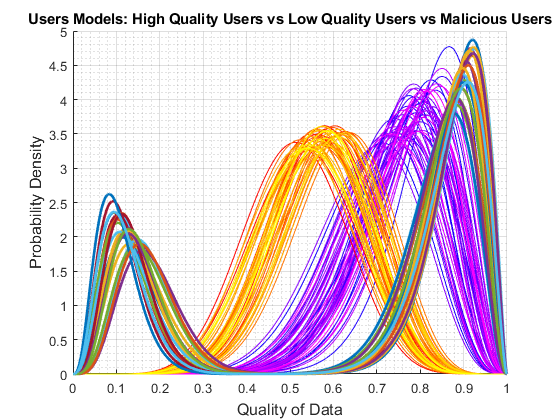

mausers1_mat = zeros(mausers_num, tasks_num);
mausers2_mat = zeros(mausers_num, tasks_num);
mausers_mat = zeros(mausers_num, tasks_num);
for i=1:mausers_num
    % High quality beta distribution model
    am1 = rand()*4 + 18; % random number in the range [18-22]
    bm1 = rand()*1 + 2.5; % random number in the range [2.5-3.5]
    amusers_pd1 = makedist('Beta', 'a', am1, 'b', bm1);
    mausers1_mat(i,:) = random(amusers_pd1, 1, tasks_num);
    % Low quality beta distribution model
    am2 = rand()*2 + 4; % random number in the range [4-6]
    bm2 = rand()*10 + 25; % random number in the range [25-35]
    amusers_pd2 = makedist('Beta', 'a', am2, 'b', bm2);
    mausers2_mat(i,:) = random(amusers_pd2, 1, tasks_num);    
    
    % the PDF for the bimodal distribution of the two beta distribution with the alpha mixture coefficient
    % bimodal_betapdf = (1-alpha)*y3 + alpha*y4
    alpha = 0.7; % mixture coefficient
    for j=1:tasks_num
        r = rand();
        if (r < alpha)
            mausers_mat(i,j) = mausers1_mat(i,j);
        else
            mausers_mat(i,j) = mausers2_mat(i,j);
        end
    end
    plot(x, alpha*pdf(amusers_pd1, x) + (1-alpha)*pdf(amusers_pd2, x),'LineWidth',2);
end
% 
title('Users Models: High Quality Users vs Low Quality Users vs Malicious Users');
xlabel('Quality of Data','FontSize',12);
ylabel('Probability Density','FontSize',12);

 grid on;
 grid minor;

% Combine the two beta distribution models for getting the bimodal distribution

## Create the scenario

- Comparison on Overall Systems

- Comparison on a specific user (as a task requester)

- Keep track of how many interactions between users after `tasks_num` tasks conducted

In comparison on overall system, we don't care who the task requesters and task providers are. We just calculate the average QoD of the whole MCS system

We just run 1000 tasks and compare the average the QoD for the all 1000 tasks.

At each task, a user will be randomly selected  as the requester for this task. Then, a random number of users among the 99 remaining users (from 2 to 50 as 2% to 50% of the total users, respectively) will be recruited based on their trust relationships. The QoD for data that the recruited users generated for this task will be obtained from the hqusers_mat, lqusers_mat, and mausers_mat.

Let's do it.

% Generate a trust relationship matrix between 100 users
% Trust scores at the bootstrap are equally set as 0.5
trust_init_value = 0.5;
exp_init_value = 0.5;
qod_init_value = 0.5;
trust_mat = ones(users_num)*trust_init_value;
exp_mat = ones(users_num)*exp_init_value;

interaction_trust_mat = zeros(users_num);
interaction_qod_mat = zeros(users_num);
interaction_avg_mat = zeros(users_num);

% Set the diagonal elements = 0
trust_mat(logical(eye(size(trust_mat)))) = 0;
exp_mat(logical(eye(size(exp_mat)))) = 0;

% For calculating Experience, it is needed to keep track of previous experience values+
exp_prev_mat = exp_mat;
% For calculating Reputation, divide into negative experiences and positive experience matrices
rep_mat = ones(users_num, 1)/users_num;
rep_pos = ones(users_num, 1)/users_num; % positive reputation
rep_neg = ones(users_num, 1)/users_num; % negative reputation

% Keep track of the average QoD for the MCS system for each task. There are tasks_num tasks so that we store the average QoD in the arrays:
trust_based_qod = zeros(tasks_num, 1); % Average QoD for the Highest Trust-based MCS scheme (Trust-based scheme)
qod_based_qod = zeros(tasks_num, 1); % Average QoD for the Highest Previous QoD scheme (QoD-based Scheme)
avg_based_qod = zeros(tasks_num, 1); % Average QoD for the Highest Average QoD scheme (Average-based Scheme)

% Create a matrix of QoD from all users in all tasks.
A = [hqusers_mat; lqusers_mat; mausers_mat];
% Random Permutation for Matrix A
shuffledA = A(randperm(size(A,1)),:);

% For a QoD-based scheme, the initial step is added in which all users have the same QoD at 0.8
A1 = [ones(users_num, 1)*qod_init_value shuffledA]; % For the initial step: no previous task, QoD of all users are same at 0.8

Error using horzcat
Dimensions of matrices being concatenated are not consistent.

% For Average-based scheme, initial step sets all users a same average of QoD at 0.5
Avg = ones(users_num, 1)*qod_init_value;

Let's run the three schemes


for i=1:tasks_num
    % Randomly select a user as the service requester
    requester = round(rand()*(users_num-1) + 1); % random number in the range [1-users_num]
    % Randomly select a number of users among the remaining users as the service providers 
    provider_num = round(rand()*(provider_max - provider_min) + provider_min); % random number in the range [provider_min, provider_max]
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%
    % Trust-based MCS System %
    %%%%%%%%%%%%%%%%%%%%%%%%%%
    
    % Select the recruited users which have the highest trust relationship with the requester.    
    [sortedX,sortingIndices_trust] = sort(trust_mat(requester, :),'descend');
    % maxValues = sortedX(1:provider_num);
    maxValueIndices_trust = sortingIndices_trust(1:provider_num);
    
    for j=1:provider_num % Consider all QoD from provider_num contributors (data providers)        
        % Update Experience value between the requester and the selected user (maxValueIndices_trust(j))
        % function [ newExp ] = expCalculation( fbValue, currentExp, previousExp)
        newExp = expCalculation(shuffledA(maxValueIndices_trust(j), i), exp_mat(requester, maxValueIndices_trust(j)), exp_prev_mat(requester, maxValueIndices_trust(j)));        
        exp_prev_mat(requester, maxValueIndices_trust(j)) = exp_mat(requester, maxValueIndices_trust(j)); % Update previous_exp_mat
        exp_mat(requester, maxValueIndices_trust(j)) = newExp; % Update the exp_mat
    end
    
    % Update interaction matrix
    interaction_trust_mat(requester, maxValueIndices_trust) = interaction_trust_mat(requester, maxValueIndices_trust) + 1;
    
    % Update Reputation value    
    [rep_pos, rep_neg] = repCalculation(rep_pos, rep_neg, exp_mat);
    rep1 = rep_pos - rep_neg;    
    rep = rep1*users_num; 
    % rep(rep < 0) = 0;   
    %rep = zeros(1, users_num);
    
    % Update Trust value
    trust_mat = (exp_mat + rep.')/2;
     
    % Calculate the average QoD for the task i
    trust_based_qod(i) = log(prod(shuffledA(maxValueIndices_trust, i))); % take the average
            
    %%%%%%%%%%%%%%%%%%%%%%%%
    % QoD-based MCS System %
    %%%%%%%%%%%%%%%%%%%%%%%%
    
    % QoD-based MCS
    % Choose the users which provide the best QoD values except the requester
    A2 = A1(:, i); 
    A2(requester) = 0;
    
    [sortedX_qod,sortingIndices_qod] = sort(A2,'descend');
    maxValueIndices_qod = sortingIndices_qod(1:provider_num);
    % Update interactions matrix    
    interaction_qod_mat(requester, maxValueIndices_qod) = interaction_qod_mat(requester, maxValueIndices_qod) + 1;    
    % Calculate the average QoD for the task i
    qod_based_qod(i) = log(prod(A1(maxValueIndices_qod, i+1))); % take the average
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Average-based MCS System %
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    Avg_temp = Avg;
    Avg_temp(requester) = 0;
    [sortedX_avg,sortingIndices_avg] = sort(Avg_temp,'descend');
    maxValueIndices_avg = sortingIndices_avg(1:provider_num);
   
    % Update interaction matrix
    interaction_avg_mat(requester, maxValueIndices_avg) = interaction_qod_mat(requester, maxValueIndices_avg) + 1; 
    % Calculate the average QoD for the task i
    avg_based_qod(i) = log(prod(shuffledA(maxValueIndices_avg, i)));
    % Update Avg
    Avg(maxValueIndices_avg) = ((Avg(maxValueIndices_avg) .* (sum(interaction_avg_mat(:, maxValueIndices_avg)).') + shuffledA(maxValueIndices_avg, i)))...
        ./((sum(interaction_avg_mat(:, maxValueIndices_avg))).' + 1);
end